# Subsonic Theoretical Calculations

## Setup

clear; clc; close all

% constants
AREA_RATIOS = [1.06, 1.00, 1.05, 1.15, 1.23, 1.27, 1.28]; % A/A*
TAP_POS_Xs = [24.7, 36.6, 48.3, 61.0, 73.7, 86.4, 99.1] % mm

TAP_POS_Xs =    24.7000   36.6000   48.3000   61.0000   73.7000   86.4000   99.1000



% data
data = matfile("data\subsonic\pressure_total_port_1.mat"); % check file


## Main

% get reference values
p_total_0 = data.totalP

p_total_0 = 1.0114e+05

p_static_0 = data.dataP_mean(1,2) % check index

p_static_0 = 9.1072e+04

u_0 = flow_pressure(p_total_0, p_static_0); % compute flow velocity at reference using bernoulli law

% pressure and mach distributions
u_dist_subsonic_theo = flow(u_0, AREA_RATIOS) % flow velocity distribution

u_dist_subsonic_theo =   120.9398  128.1962  122.0916  111.4749  104.2245  100.9419  100.1532


p_dist_subsonic_theo = pressure(p_static_0, u_dist_subsonic_theo) % pressure distribution

p_dist_subsonic_theo = 	1.0e+04 *

    8.2113    8.1006    8.1941    8.3460    8.4418    8.4831    8.4928


m_dist_subsonic_theo = mach(u_dist_subsonic_theo, p_dist_subsonic_theo) % mach number distribution 

m_dist_subsonic_theo =     0.3948    0.4213    0.3990    0.3609    0.3355    0.3242    0.3215




% uncertainty WIP
p_dist_subsonic_theo_unc = [1, 1, 1, 1, 1, 1, 1]

p_dist_subsonic_theo_unc =      1     1     1     1     1     1     1


m_dist_subsonic_theo_unc = [0.01, 0.01, 0.01, 0.01, 0.01, 0.01, 0.01]

m_dist_subsonic_theo_unc =     0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100


## Plots

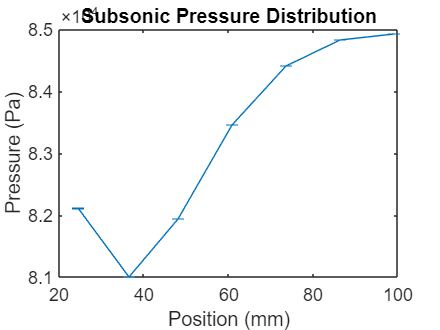


% pressure distribution
figure
errorbar(TAP_POS_Xs, p_dist_subsonic_theo, p_dist_subsonic_theo_unc)
title("Subsonic Pressure Distribution")
xlabel("Position (mm)");
ylabel("Pressure (Pa)");

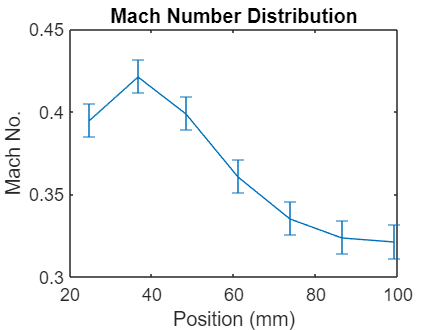


% mach distribution
figure
errorbar(TAP_POS_Xs, m_dist_subsonic_theo, m_dist_subsonic_theo_unc)
title("Mach Number Distribution")
xlabel("Position (mm)");
ylabel("Mach No.");

## Functions

function p = pressure(p_0, u)
    % Computes the static pressure from bernoulli equation (assumes isentropic flow)
    %
    % Args:
    %   p_0: Static pressure at reference point
    %   u: flow velocity at point where pressure is to be calculated

    RHO = 1.225; % kg/m^3
    
    p = p_0 - 1/2*RHO*u.^2;
end

function u = flow_pressure(p_total, p_static)
    % Computes the flow velocity from bernoulli law using total pressure
    % and static pressure measured at the same point
    % Args:
    %   p_total: Total pressure (static + dynamic) [Pa]
    %   p_static: Static pressure [Pa]
    
    RHO = 1.225; % kg/m^3

    u = sqrt(2*(p_total - p_static)/RHO);
end

function u = flow(u_0, area_ratio)
    % Computes the flow velocity from continuity equation (assumes incompressible flow) 
    % using reference flow velocity and ratio between area at point of
    % interest and reference chamber area.
    % 
    % Args:
    %   u_0: flow velocity at reference [m/s]
    %   area_ratio: ratio between area of chamber at point where 'u' is
    %       being calculated and chamber area where 'u_0' was obtained

    u = u_0 * area_ratio.^-1;
end

function m = mach(u, p)
    % Computes the mach number.
    %
    % Args:
    %   u: local flow velocity [m/s]
    %   p: local static pressure [Pa]
    
    v = sound(p);
    m = u ./ v;
end

function v = sound(p)
    % Computes the mach number for a given pressure.
    %
    % Args:
    %   p: local static pressure [Pa]

    RHO = 1.225; % density of standard air kg/m^3
    GAMMA = 1.4; % heat capacity ratio of standard air

    v = sqrt(GAMMA*p/RHO);
end
